m = 1.5; % kg
rho = 1.225; % kg/m^3
v_inf = 20; % m/s
S = 25*1E-4; % m^2
Cl_alpha = 2*pi; % rad^(-1)

numOLTF = [1/2*rho*v_inf^2*S*Cl_alpha];
denOLTF = [m 0 0];

OLTF = tf(numOLTF,denOLTF)

OLTF =
 
   3.848
  -------
  1.5 s^2
 
Continuous-time transfer function.
Model Properties


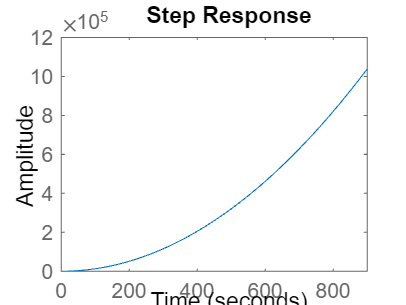


step(OLTF)


CLTF = feedback(OLTF,1)

CLTF =
 
       3.848
  ---------------
  1.5 s^2 + 3.848
 
Continuous-time transfer function.
Model Properties



[numCLTF,denCLTF]=tfdata(CLTF);
numCLTF=cell2mat(numCLTF)

numCLTF =          0         0    3.8485


denCLTF=cell2mat(denCLTF)

denCLTF =     1.5000         0    3.8485



rts = roots(denCLTF)

rts =    0.0000 + 1.6018i
   0.0000 - 1.6018i


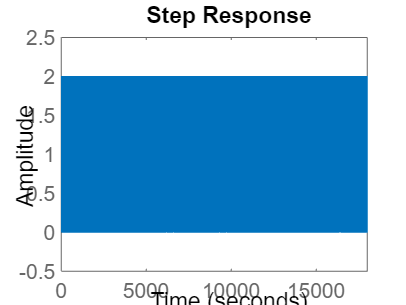


step(CLTF)


Kp = 1.3639e+06;
Ki = 1.1935e+08;
Kd = 3.8965e+03;

C = pid(Kp,Ki,Kd);

OLTF_C = series(OLTF,C)

OLTF_C =
 
  1.5e04 s^2 + 5.249e06 s + 4.593e08
  ----------------------------------
               1.5 s^3
 
Continuous-time transfer function.
Model Properties


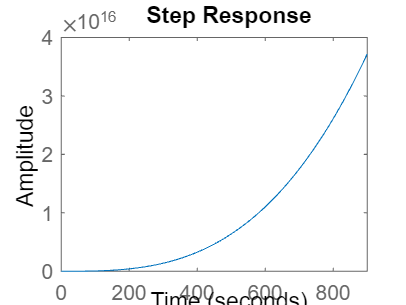


step(OLTF_C)


CLTF_C = feedback(OLTF_C,1)

CLTF_C =
 
       1.5e04 s^2 + 5.249e06 s + 4.593e08
  --------------------------------------------
  1.5 s^3 + 1.5e04 s^2 + 5.249e06 s + 4.593e08
 
Continuous-time transfer function.
Model Properties


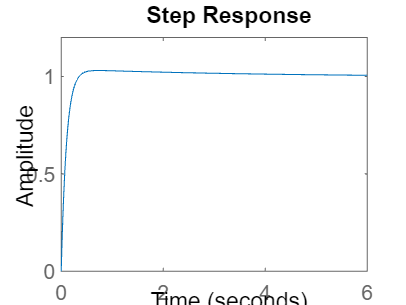


step(CLTF_C)


[numCLTF_C,denCLTF_C]=tfdata(CLTF_C);
numCLTF_C=cell2mat(numCLTF_C)

numCLTF_C = 1.0e+08 *

         0    0.0001    0.0525    4.5931


denCLTF_C=cell2mat(denCLTF_C)

denCLTF_C = 1.0e+08 *

    0.0000    0.0001    0.0525    4.5931
